**Neural Aanalysis for Song Timing**

- Example song and segmentation of syllables and gaps 

- Visualizing neural activity aligned to behavior

- Measuring activity at target time period and correlation with behavior

- Test whether the frequency of significant correlations is above chance

**Example song and segmentation of syllables and gaps **

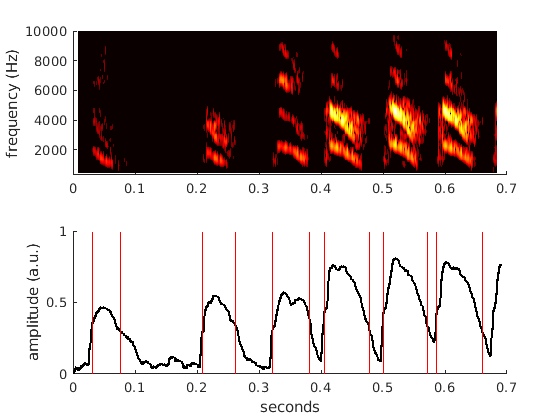

summarymat = 'combined_data_G26G23_MU_5_29_2006_1530_1540_PCA_CH0_TH_recommended.mat';
pathfile = '/media/jcheung/MyPassport/Sober_data_RA_phones/RA_physiology/Mel_RA_birds/G26G23/05292006/SU2/';
songfilenm = 'G26-G23-05292006.200.cbin';
motif = 'abcddd';

%load labels, onsets/offsets for song file, and raw waveform
load([pathfile,songfilenm,'.not.mat'])
ind = strfind(labels,motif);
[dat fs] = evsoundin(pathfile,songfilenm,'obs0r');
dat = dat(motifstart:motifend);
filtsong=bandpass(dat,fs,300,10000,'hanningffir');
sm=evsmooth(dat,fs,'','','',10,300,10000,'hanningffir');
motifstart = floor((onsets(ind(1))-32)*1e-3*fs);%sample number denoting the start of the first rendition of target motif in this file
motifend = ceil((offsets(ind(1)+length(motif)-1)+32)*1e-3*fs);%sample number denoting the end of motif
ons = (onsets(ind(1):ind(1)+length(motif)-1))*1e-3*fs;%onsets for each individual syllable in motif, in samples
offs = (offsets(ind(1):ind(1)+length(motif)-1))*1e-3*fs;%offsets for each individual syllable in motif, in samples

%spectrogram of song motif
[sp f tm] = jc_spectrogram(filtsong,fs,0);
figure;subplot(2,1,1);hold on;
imagesc(tm,f,log(abs(sp)));axis('xy');colormap('hot');ylabel('frequency (Hz)');
ylim([300 10000])

%smoothed amplitude envelop
t = [0:length(sm)-1]./fs;
subplot(2,1,2);hold on
sm = log10(sm);
sm = (sm-min(sm))./max(sm);
plot(t,sm,'k','linewidth',2);hold on;
plot(([ons ons]-motifstart)./fs,[0 1],'r');
plot(([offs offs]-motifstart)./fs,[0 1],'r');
xlabel('seconds');ylabel('amplitude (a.u.)')

**Visualizing neural activity aligned to behavior**

%parameters 
pathfile = '/media/jcheung/MyPassport/Sober_data_RA_phones/RA_physiology/RA_data_summaries_putative_proj_neurons/';
seqlen = 6;%number of syllables in sequence
motorwin = -40;%premotor window
load([pathfile,summarymat])
win = gausswin(10);%for smoothing spike trains, ms
win = win./sum(win);
spiketimes = spiketimes*1000;%ms

%extract all onsets/offsets of instance of target motif and get target gap duration for each trial
idx = strfind(labels,motif);
gapdurs_all = onsets(2:end)-offsets(1:end-1);
seqons = onsets(bsxfun(@plus, idx',(0:seqlen-1)));%realtime in seconds 
seqoffs = offsets(bsxfun(@plus,idx',(0:seqlen-1)));
dur_id = jc_removeoutliers(gapdurs_all(idx+seqlen/2-1),3);
id = find(isnan(dur_id));dur_id(id) = [];seqons(id,:) = [];seqoffs(id,:) = [];

%remove trials where sequence length > 1 sec and re-order trials by target gap duration
if ~isempty(find(seqoffs(:,end)-seqons(:,1)>=1000))
    id = find(seqoffs(:,end)-seqons(:,1)>=1000);
    seqons(id,:) = [];seqoffs(id,:) = [];dur_id(id) = [];
end
[~,ix] = sort(dur_id,'descend');
dur_id = dur_id(ix);seqons = seqons(ix,:);seqoffs = seqoffs(ix,:);

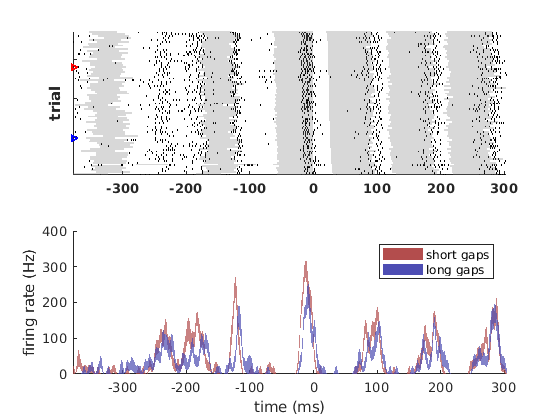

%compute PSTH from spike trains aligned to onset of target gap duration
anchor = seqoffs(:,seqlen/2);
seqst = ceil(max(anchor-seqons(:,1)));%start of sequence relative to target in ms
seqend = ceil(max(seqoffs(:,end)-anchor));%end of sequence 
[PSTH_mn tb smooth_spiketrains spktms] = smoothtrain(spiketimes,seqst,seqend,anchor,win);

%plot PSTH aligned with spike rasters

%find top and bottom quartile of gap durations
thr1 = quantile(dur_id,0.25);%threshold for small gaps
smallgaps_id = find(dur_id <= thr1);
thr2 = quantile(dur_id,0.75);%threshold for large gaps
largegaps_id = find(dur_id >= thr2);

%raster of spiketimes in each trial aligned to target gap
figure;ax1=subplot(2,1,1);hold on
cnt=0;
for m = 1:length(dur_id)
    if ~isempty(spktms{m})
        plot(repmat(spktms{m},2,1),[cnt cnt+1],'k');hold on;
    end
    for syll=1:size(seqons,2) %bars to denote syllable boundaries
        patch([seqons(m,syll) seqoffs(m,syll) seqoffs(m,syll) seqons(m,syll)]-anchor(m),...
             [cnt cnt cnt+1 cnt+1],[0.5 0.5 0.5],'edgecolor','none','facealpha',0.3);hold on;
    end
    cnt=cnt+1;
end
ylabel('trial');set(gca,'fontweight','bold');
xlim([-seqst seqend]);ylim([0 cnt]);yticklabels('')
plot(-seqst,min(smallgaps_id),'r>','markersize',4,'linewidth',2);hold on;
plot(-seqst,max(largegaps_id),'b>','markersize',4,'linewidth',2);hold on;

%average FR for top and bottom quartile of gap durations 
ax2=subplot(2,1,2);hold on;
patch([-seqst:seqend fliplr(-seqst:seqend)],([mean(smooth_spiketrains(smallgaps_id,:),1)-...
        stderr(smooth_spiketrains(smallgaps_id,:),1)...
        fliplr(mean(smooth_spiketrains(smallgaps_id,:),1)+...
        stderr(smooth_spiketrains(smallgaps_id,:),1))])*1000,[0.7 0.3 0.3],'edgecolor','none','facealpha',0.7);
patch([-seqst:seqend fliplr(-seqst:seqend)],([mean(smooth_spiketrains(largegaps_id,:),1)-...
        stderr(smooth_spiketrains(largegaps_id,:),1)...
        fliplr(mean(smooth_spiketrains(largegaps_id,:),1)+...
        stderr(smooth_spiketrains(largegaps_id,:),1))])*1000,[0.3 0.3 0.7],'edgecolor','none','facealpha',0.7);
xlim([-seqst seqend]);xlabel('time (ms)');ylabel('firing rate (Hz)')
legend({'short gaps','long gaps'})

**Measuring activity at target time period and correlation with behavior**

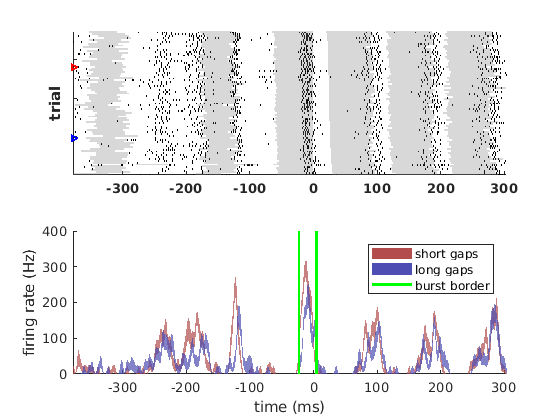

%identify periods of high firing within premotor window

%shuffled spike train to detect peaks that are significantly
%above shuffled activity
smooth_spiketrains_rand = permute_rowel(smooth_spiketrains);
smooth_spiketrains_rand = conv2(1,win,smooth_spiketrains_rand,'same');
PSTH_mn_rand = mean(smooth_spiketrains_rand,1).*1000;

%identify peaks in PSTH within premotor window 
[pks, locs] = findpeaks2(PSTH_mn,'MinPeakProminence',20,'MinPeakWidth',10,...
    'MinPeakDistance',15,'MinPeakHeight',mean(PSTH_mn_rand)+20,...
    'Annotate','extents','WidthReference','halfheight');
pkid = find(tb(locs)>=motorwin & tb(locs)<=0);

%identify the borders of the firing burst 
FRbelow = find(PSTH_mn<=mean(PSTH_mn_rand));
if FRbelow(1) ~= 1
    FRbelow = [1 FRbelow];
elseif FRbelow(end) ~= length(tb)
    FRbelow = [FRbelow length(tb)];
end
burstst = FRbelow(find(diff(locs(pkid)-FRbelow>0)<0));
burstend = FRbelow(find(diff(locs(pkid)-FRbelow<0)==1)+1);

%visualize the identified burst
yl = get(ax2,'ylim');
plot(ax2,repmat([tb(burstst) tb(burstend)],2,1),yl,'g','linewidth',2);
legend({'short gaps','long gaps','burst border'})

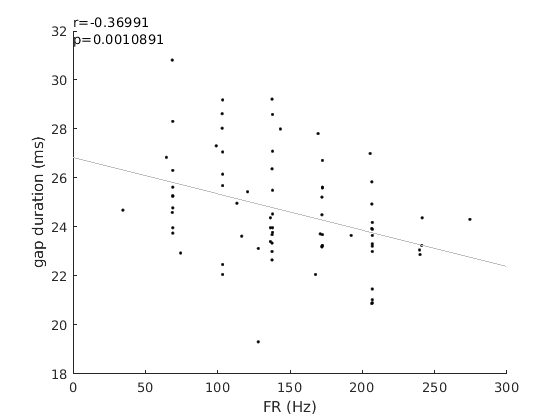

%extract mean FR in premotor window and regress with gap duration for each trial
npks_burst = mean(smooth_spiketrains(:,burstst:burstend),2).*1000;  
[r p] = corrcoef(dur_id,npks_burst);
figure;scatter(npks_burst,dur_id,'k.');hold on;lsline
ylabel('gap duration (ms)');xlabel('FR (Hz)')
text(0,1,{['r=',num2str(r(2))];['p=',num2str(p(2))]},'units','normalized',...
    'horizontalalignment','left')

**Test whether the frequency of significant correlations is above chance**

%shuffle test for Monte Carlo analysis on frequency of significant correlations in all neuron-behavior cases
numtrials = 1000;
npks_burst_shuff = repmat(npks_burst',numtrials,1);
npks_burst_shuff = permute_rowel(npks_burst_shuff);
[shuffR shuffP] = corrcoef([npks_burst_shuff',dur_id]);
shuffR =shuffR(1:end-1,end);%pvalues for the correlation of 1000 shuffle trials
shuffP = shuffP(1:end-1,end);%corr coef for the correlation of 1000 shuffle trials

%population analysis on the frequency of significant correlations

%load data from each firing burst-behavior case, stored into a table
load([pathfile,'gap_multicorrelation_analysis_fr.mat'])
listofsingleunits = 'singleunits_leq_1pctISI_2pcterr';
ff = load_batchf([pathfile,listofsingleunits]);
id = [];
for i = 1:length(ff)
    id = [id;find(cellfun(@(x) contains(ff(i).name,x),corrtable10.unitid))];
end
corrtable = corrtable10(id,:);
corrtable.Properties.VariableNames'

ans = 14×1 cell array
    {'birdid'          }
    {'unitid'          }
    {'seqid'           }
    {'burstid'         }
    {'alignby'         }
    {'pkFR'            }
    {'pkactivity'      }
    {'width'           }
    {'pct_error'       }
    {'ntrials'         }
    {'trialbytrialcorr'}
    {'latency'         }
    {'corrs'           }
    {'shuffle'         }


height(corrtable)%each row is a case: 184 active neurons paired with a target sequence from a specific bird 

ans = 184

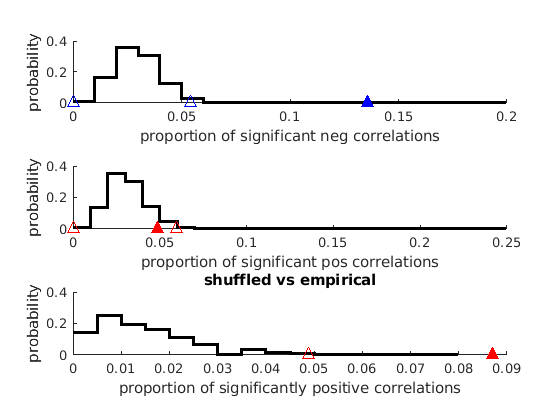

%determine empirical values for frequency of significant negative/positive correlations
activitythresh = 50; %hz
negcorr = find(corrtable.pkFR>=activitythresh & ...
    cellfun(@(x) x(1),corrtable.corrs(:,2))<=0.05 & cellfun(@(x) x(1),corrtable.corrs(:,1))<0);
poscorr = find(corrtable.pkFR>=activitythresh & ...
    cellfun(@(x) x(1),corrtable.corrs(:,2))<=0.05 & cellfun(@(x) x(1),corrtable.corrs(:,1))>0);
activecases = find(corrtable.pkFR>=activitythresh);

numcases = length(activecases);
numsignificant = length(find(corrtable.pkFR>=activitythresh & ...
    cellfun(@(x) x(1),corrtable.corrs(:,2))<=0.05));

%determine the frequency of significant negative/positive correlations by chance
aph = 0.01;
shuffcorr = cell2mat(cellfun(@(x) x(:,1),corrtable(activecases,:).shuffle(:,1),'un',0)');
shuffpval = cell2mat(cellfun(@(x) x(:,1),corrtable(activecases,:).shuffle(:,2),'un',0)');

randnumsignificantnegcorr = sum((shuffpval<=0.05).*(shuffcorr<0),2);
randpropsignificantnegcorr = randnumsignificantnegcorr./size(shuffpval,2);
randpropsignificantnegcorr_sorted = sort(randpropsignificantnegcorr);
randpropsignificantnegcorr_lo = randpropsignificantnegcorr_sorted(floor(aph*numtrials/2));
randpropsignificantnegcorr_hi = randpropsignificantnegcorr_sorted(ceil(numtrials-(aph*numtrials/2)));

randnumsignificantposcorr = sum((shuffpval<=0.05).*(shuffcorr>0),2);
randpropsignificantposcorr = randnumsignificantposcorr./size(shuffpval,2);
randpropsignificantposcorr_sorted = sort(randpropsignificantposcorr);
randpropsignificantposcorr_lo = randpropsignificantposcorr_sorted(floor(aph*numtrials/2));
randpropsignificantposcorr_hi = randpropsignificantposcorr_sorted(ceil(numtrials-(aph*numtrials/2)));

randdiffprop = abs(randpropsignificantnegcorr-randpropsignificantposcorr);
randdiffprop_sorted = sort(randdiffprop);
randdiffprop_lo = randdiffprop_sorted(floor(aph*numtrials/2));
randdiffprop_hi = randdiffprop_sorted(ceil(numtrials-(aph*numtrials/2)));

%distribution of frequency of significant correlations for shuffled data
figure;subplot(3,1,1);hold on;
[n b] = hist(randpropsignificantnegcorr,[0:0.01:0.2]);
stairs(b,n/sum(n),'k','linewidth',2);y=get(gca,'ylim');
plot(randpropsignificantnegcorr_hi,y(1),'b^','markersize',8);hold on;
plot(randpropsignificantnegcorr_lo,y(1),'b^','markersize',8);hold on;
mn = sum(length(negcorr))/numcases;
plot(mn,y(1),'b^','markersize',8,'markerfacecolor','b');hold on;
xlabel('proportion of significant neg correlations');ylabel('probability');

subplot(3,1,2);hold on;
[n b] = hist(randpropsignificantposcorr,[0:0.01:0.25]);
stairs(b,n/sum(n),'k','linewidth',2);y=get(gca,'ylim');
plot(randpropsignificantposcorr_lo,y(1),'r^','markersize',8);hold on;
plot(randpropsignificantposcorr_hi,y(1),'r^','markersize',8);hold on;
mn = length(poscorr)/numcases;
plot(mn,y(1),'r^','markersize',8,'markerfacecolor','r');hold on;
xlabel('proportion of significant pos correlations');ylabel('probability');

subplot(3,1,3);hold on;
[n b] = hist(randdiffprop,[0:0.005:0.08]);
stairs(b,n/sum(n),'k','linewidth',2);y=get(gca,'ylim');
plot(randdiffprop_hi,y(1),'r^','markersize',8);hold on;
mn = abs(length(negcorr)-length(poscorr))/numcases;
plot(mn,y(1),'r^','markersize',8,'markerfacecolor','r');hold on;
title('shuffled vs empirical');
xlabel('proportion of significantly positive correlations');ylabel('probability');

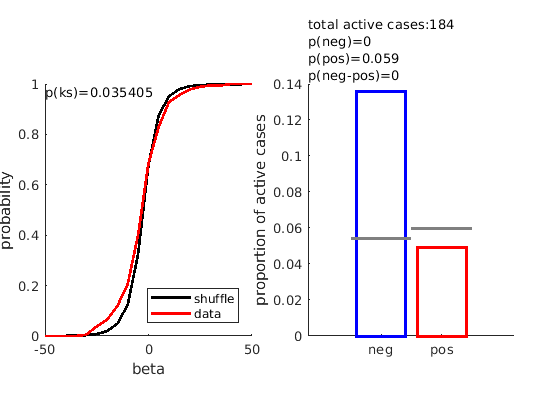

%plot distribution of correlation values for empirical vs shuffled data
figure;subtightplot(1,2,1,0.1,0.2,0.08);hold on;
[n b] = hist(shuffcorr(:),[-100:5:100]);
cdfshuff = cumsum(n/sum(n));
plot(b,cdfshuff,'k','linewidth',2);hold on;
[n b] = hist([cellfun(@(x) x(1),corrtable(activecases,:).corrs(:,1))],[-100:5:100]);
cdfdata = cumsum(n/sum(n));
plot(b,cdfdata,'r','linewidth',2);hold on;
xlabel('beta');ylabel('probability');xlim([-50 50])
[h p3] = kstest2([cellfun(@(x) x(1),corrtable(activecases,:).corrs(:,1))],shuffcorr(:));
p4 = length(find(randdiffprop>=abs((length(negcorr)/numcases)-(length(poscorr)/numcases))))/numtrials;
p6 = length(find(randpropsignificantposcorr>=length(poscorr)/numcases))/numtrials;
p7 = length(find(randpropsignificantnegcorr>=length(negcorr)/numcases))/numtrials;
text(0,1,{['p(ks)=',num2str(p3)]},'units','normalized','verticalalignment','top');legend({'shuffle','data'},'location','southeast')

subtightplot(1,2,2,0.1,0.2,0.08);hold on;
ax = bar([length(negcorr)/numcases,length(poscorr)/numcases],'facecolor','none','linewidth',2,'EdgeColor','flat');
ax.CData(1,:) = [0 0 1];
ax.CData(2,:) = [1 0 0];
plot([0.5 1.5],[randpropsignificantnegcorr_hi randpropsignificantnegcorr_hi],'color',[0.5 0.5 0.5],'linewidth',2);hold on;
plot([1.5 2.5],[randpropsignificantposcorr_hi randpropsignificantposcorr_hi],'color',[0.5 0.5 0.5],'linewidth',2);hold on;
xticks([1 2]);xticklabels({'neg','pos'});
ylabel('proportion of active cases');
text(0,1,{['total active cases:',num2str(numcases)];...
['p(neg)=',num2str(p7)];['p(pos)=',num2str(p6)];...
['p(neg-pos)=',num2str(p4)]},'units','normalized',...
'verticalalignment','bottom');

% mixed effects model to estimate relationship between activity and gap duration while 
%controlling for other variables

ff = load_batchf(listofsingleunits);
id = [];
for i = 1:length(ff)
    id = [id;find(cellfun(@(x) contains(ff(i).name,x),dattable10.unitid))];
end
dattable = dattable10(id,:);
dattable.Properties.VariableNames'

ans = 14×1 cell array
    {'dur'      }
    {'spikes'   }
    {'pct_error'}
    {'burstvar' }
    {'pkFR'     }
    {'activity' }
    {'birdid'   }
    {'unitid'   }
    {'seqid'    }
    {'burstid'  }
    {'vol1'     }
    {'vol2'     }
    {'dur1'     }
    {'dur2'     }


height(dattable) %each row is a single trial of neural activity from a specific unit/sequence/bird with behavior

ans = 12315


%normalizing variables
activecases  = find(dattable.pkFR>=activitythresh);
subset = dattable(activecases,:);
cases = unique(subset(:,{'unitid','seqid','burstid'}));
for i = 1:size(cases,1)
    ind = find(strcmp(subset.unitid,cases(i,:).unitid) & ...
        strcmp(subset.seqid,cases(i,:).seqid) & subset.burstid==cases(i,:).burstid);
    dur = subset(ind,:).dur;
    dur = (dur-mean(dur))/std(dur);
    dur1 = subset(ind,:).dur1;
    dur1 = (dur1-mean(dur1))/std(dur1);
    dur2 = subset(ind,:).dur2;
    dur2 = (dur2-mean(dur2))/std(dur2);
    vol1 = subset(ind,:).vol1;
    vol1 = (vol1-mean(vol1))/std(vol1);
    vol2 = subset(ind,:).vol2;
    vol2 = (vol2-mean(vol2))/std(vol2);
    subset(ind,:).vol1 = vol1;
    subset(ind,:).vol2 = vol2;
    subset(ind,:).dur = dur;
    subset(ind,:).dur1 = dur1;
    subset(ind,:).dur2 = dur2;
end
subset.burstid = nominal(subset.burstid);

%estimate relationship between gap duration and firing rate while controlling for volume and duration of bordering syllables
formula = ['spikes ~ dur + vol1 + vol2 + dur1 + dur2 + burstid + (1+dur+vol1+vol2+dur1+dur2+burstid|unitid:seqid)',...
    '+(1+dur+vol1+vol2+dur1+dur2+burstid|unitid) + (1+dur+vol1+vol2+dur1+dur2+burstid|birdid)'];
mdl = fitlme(subset,formula)

mdl = Linear mixed-effects model fit by ML

Model information:
    Number of observations           12315
    Fixed effects coefficients           7
    Random effects coefficients       1512
    Covariance parameters               85

Formula:
    spikes ~ 1 + dur + burstid + vol1 + vol2 + dur1 + dur2 + (1 + dur + burstid + vol1 + vol2 + dur1 + dur2 | unitid:seqid) + (1 + dur + burstid + vol1 + vol2 + dur1 + dur2 | unitid) + (1 + dur + burstid + vol1 + vol2 + dur1 + dur2 | birdid)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.2834e+05    1.2903e+05    -64080           1.2816e+05

Fixed effects coefficients (95% CIs):
    Name                 Estimate    SE         tStat       DF       pValue        Lower       Upper   
    '(Intercept)'          149.42     24.388      6.1266    12308    9.2509e-10      101.61      197.22
    'dur'                  -4.011     

mdl.Rsquared

ans = struct with fields:
    Ordinary: 0.5622
    Adjusted: 0.5620


function [PSTH_mn tb smooth_spiketrains spktms] = smoothtrain...
        (spiketimes,seqst,seqend,anchor,win);
    %PSTH of smoothed spike trains across trials 
    spktms = cell(size(anchor,1),1);%spike times for each trial relative to target gap 
    smooth_spiketrains = zeros(size(anchor,1),seqst+seqend+1);
    for m = 1:size(anchor,1)
        temp = zeros(1,seqst+seqend+1);
        x = spiketimes(find(spiketimes>=(anchor(m)-seqst) & spiketimes<=(anchor(m)+seqend)));
        spktms{m} = x - anchor(m); 
        spktimes = round(spktms{m})+seqst+1;
        temp(spktimes) = 1;
        smooth_spiketrains(m,:) = conv(temp,win,'same');
    end
    tb = [-seqst:seqend];
    PSTH_mn = mean(smooth_spiketrains,1).*1000;%spikes/second
end

function shuffmat = permute_rowel(mat);
    %shuffle elements within rows in matrix
    [~,permmat] = sort(rand(size(mat,1),size(mat,2)),2);
    permmat = (permmat-1)*size(mat,1)+ndgrid(1:size(mat,1),1:size(mat,2));
    shuffmat = mat(permmat);
end